# Neuro street view example script 

## Define paths and parameters

#### Define where to save your data and where your Allen Atlas data is located

saveLocation = '/home/julie/Dropbox/Data/AllenQueries';
allenAtlasPath =  '/home/julie/Dropbox/Atlas/allenCCF'; % download from: https://figshare.com/articles/dataset/Modified_Allen_CCF_2017_for_cortex-lab_allenCCF/25365829 
fileName = ''; % leave empty to recompute each time, or enter text (e.g. fileName = 'Visual_projections') to save and reload

#### Input information about the regions and experiments you want to plot 

inputRegions = {'VISal'}; % region(s), use Allen Atlas abbreviation conventions
    % or if you already have experiment IDs , skip step 1 below and input
    % them directly in step 2
mouseLine = ''; % leave empty to include all 
primaryInjection = true; % boolean, search for injections where 'injection' was the primary or not


#### Define your plotting parameters 

subtractOtherHemisphere = false;
normalizationMethod = 'injectionIntensity'; % can be 'none' or 'injectionIntensity'
loadAll = false; % if true, will load a 132 x 80 x 114 x number of experiments matrix instead of 132 x 80 x 114. 
numberOfSlices = 10;
numberOfPixels = 15;
outputRegions = {'CP'};


% future features - these are not implemented yet
color = [0.543,0, 0; ...
    0, 0.746, 1;...
    0.180,0.543,0.340;...
    1,0.547,0]; % - not implemented yet - outline color for each region in RGB. leave empty to use defaults 
plane = 'coronal'; % - not implemented yet - coronal or sagital
smoothing = 2; % - not implemented yet - none or a number (of pixels)
colorLimits = 'global'; % - not implemented yet - global, per slice or two numbers  
regionOnly = true; % - not implemented yet - 

## Get all Allen connectivity experiments of interest 

experimentIDs = bsv.findConnectivityExperiments(inputRegions, mouseLine, primaryInjection);

Found 283 experiments in VISp 
Found 68 experiments in VISl 
Found 18 experiments in VISal 
Found 38 experiments in VISam 
Found 15 experiments in VISpl 
Found 28 experiments in VISpm 
Found 14 experiments in VISli 
Found 36 experiments in VISpor 


## Fetch/load experiment data 

[experimentImgs, injectionSummary, experimentImgs_perExperiment] = bsv.fetchConnectivityData(experimentIDs, saveLocation, fileName, normalizationMethod, subtractOtherHemisphere, '', '', loadAll);

## Plot projection data (in 2D) 

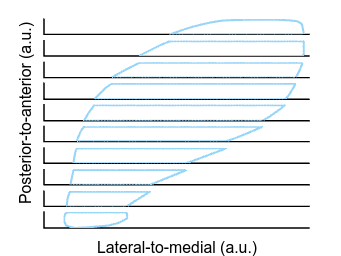

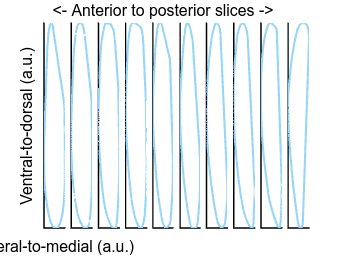

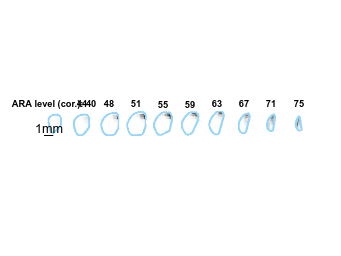

bsv.plotConnectivity(experimentImgs, allenAtlasPath, outputRegions(1), numberOfSlices, numberOfPixels, plane, regionOnly, smoothing, colorLimits, color);

## Plot injections

**2D, region by region**

Warning: This will generate a lot of plots if you have several injection regions (3 plots/region).

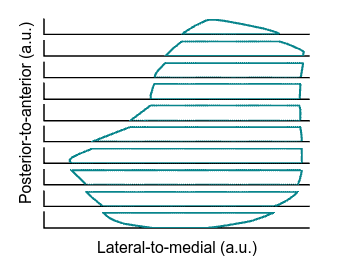

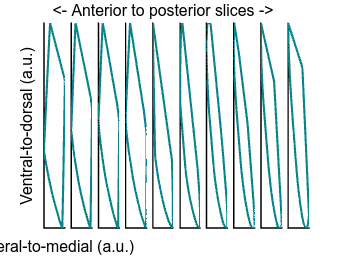

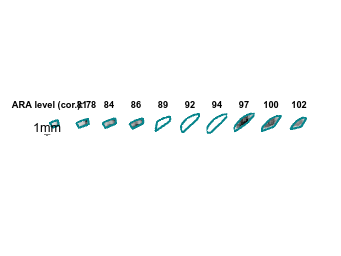

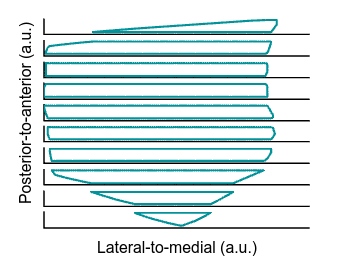

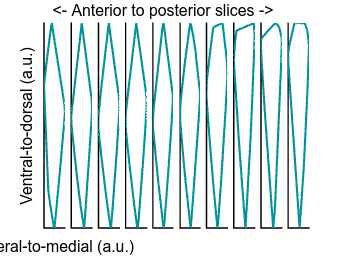

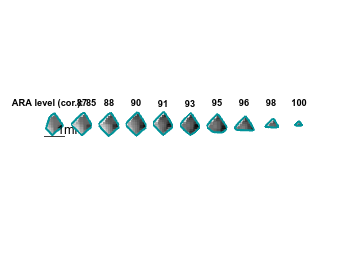

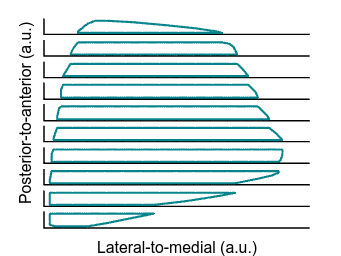

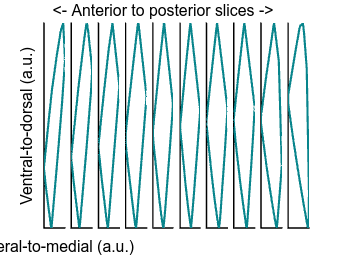

for iInputRegion = 1:size(inputRegions,2)
    bsv.plotConnectivity(experimentImgs, allenAtlasPath, inputRegions(iInputRegion), numberOfSlices, numberOfPixels, plane, regionOnly, smoothing, colorLimits, color);
end


%% b. 2D, all regions - QQ TO DO
% bsv.plotConnectivity(experimentImgs, allenAtlasPath, inputRegions, numberOfSlices, numberOfPixels, plane, regionOnly, smoothing, colorLimits, color)

#### 3D, all regions

Warning: the dot size here is not reflective of the true injection vlume, it is just for visualization purposes. 

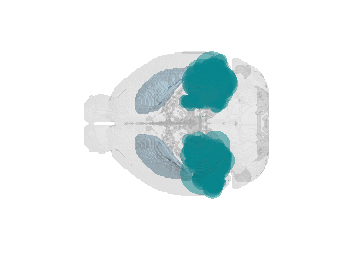

plotPatch = true; % if true plots a full volume; if false, plots a grid
bsv.plotConnectivity3D(injectionSummary, allenAtlasPath, outputRegions(1), color, plotPatch);